# Adaptive Algorithms

clear; clc;
cd('/Users/duncan/OneDrive - University of Delaware - o365/Documents/Presentations/Adaptive_algorithms')

## Up/Down

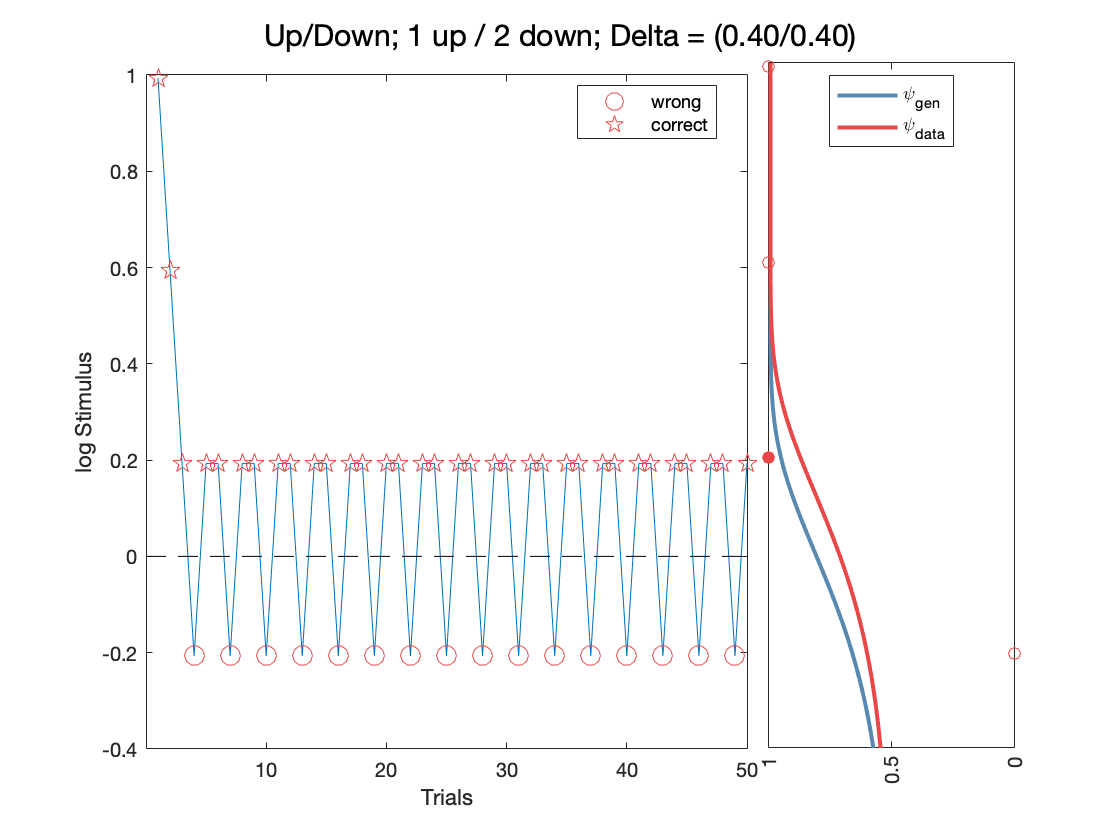

clear; clc;

% Parameters 
Up = 1; 
Down = 2;
delta = [0.4, 0.4]; 
% generating
alpha_gen = 0;
beta_gen = 2;
lambda_gen = 0.01;
gamma_gen = 0.5;
% assumed 
beta_assume = 2;
lambda_assume = 0.01;
gamma_assume = 0.5;

% Simulate 
UpDown(Up, Down, delta, alpha_gen, beta_gen, lambda_gen, gamma_gen, beta_assume, lambda_assume, gamma_assume); 

## The best PEST


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

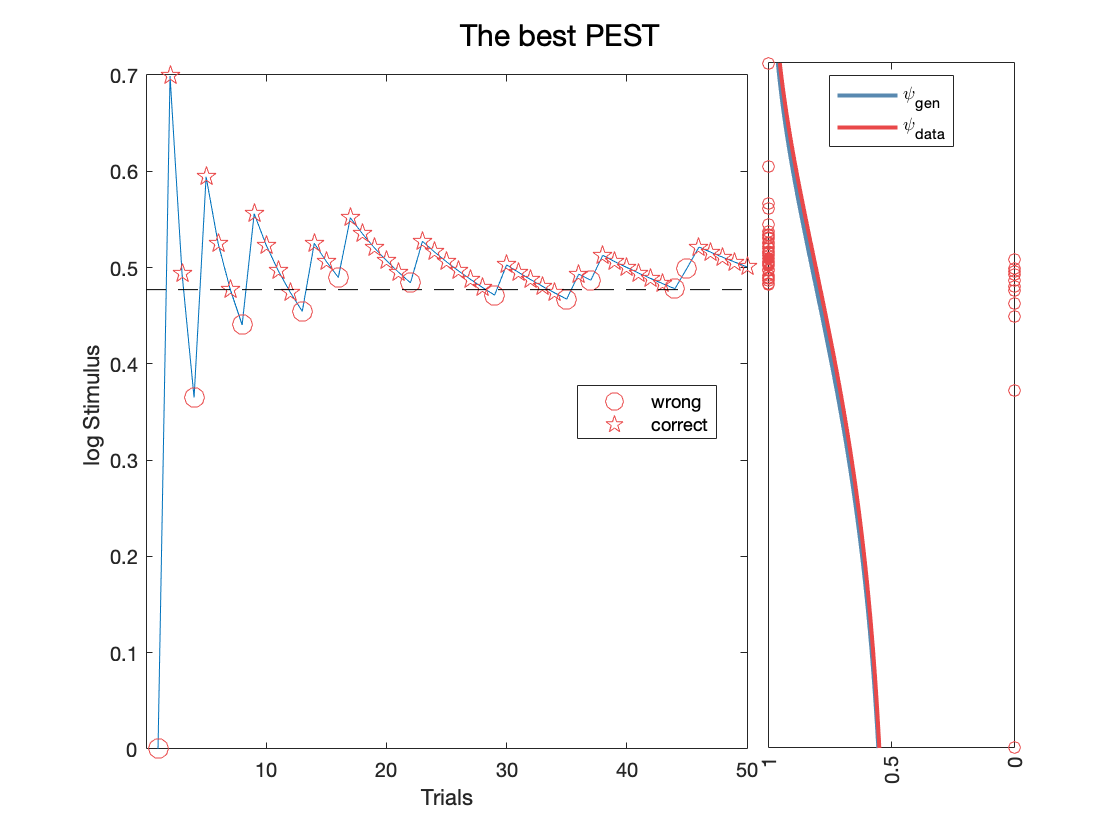

clear; clc;

% Generating parameters 
beta_gen = 2;
gamma_gen = 0.5;
lambda_gen = 0.01;

% Assumed parameters 
beta_assume = 2;
gamma_assume = 0.5;
lambda_assume = 0.01;

% Simulate 
bestPEST(beta_gen, gamma_gen, lambda_gen, beta_assume, gamma_assume, lambda_assume, 'n'); 

## The Quest

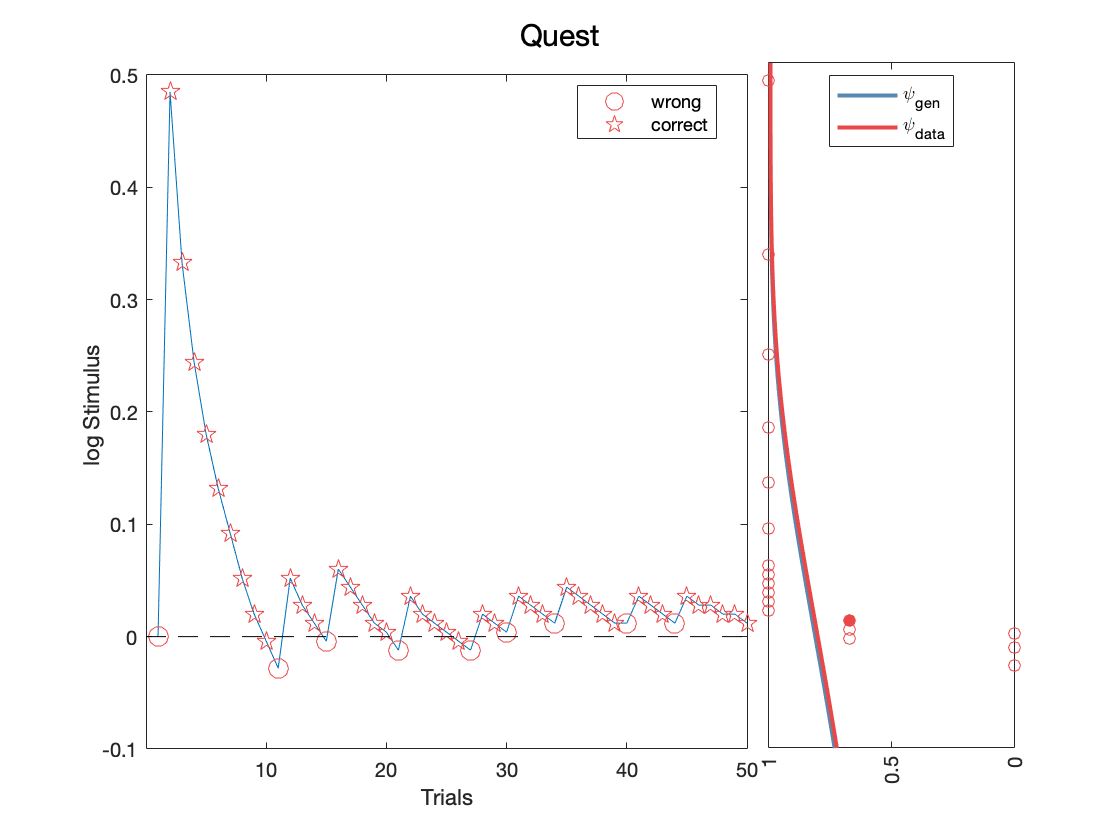

clear; clc;

% Generating parameters 
beta_gen = 2;
gamma_gen = 0.5;
lambda_gen = 0.01;

% Assumed parameters 
beta_assume = 2;
gamma_assume = 0.5;
lambda_assume = 0.01;

% Simulate 
Quest(beta_gen, beta_assume, gamma_gen, gamma_assume, lambda_gen, lambda_assume, 'y');

## Psi

clear; clc;


## Psi-Marginal

clear; clc;


## UpDown Simulations

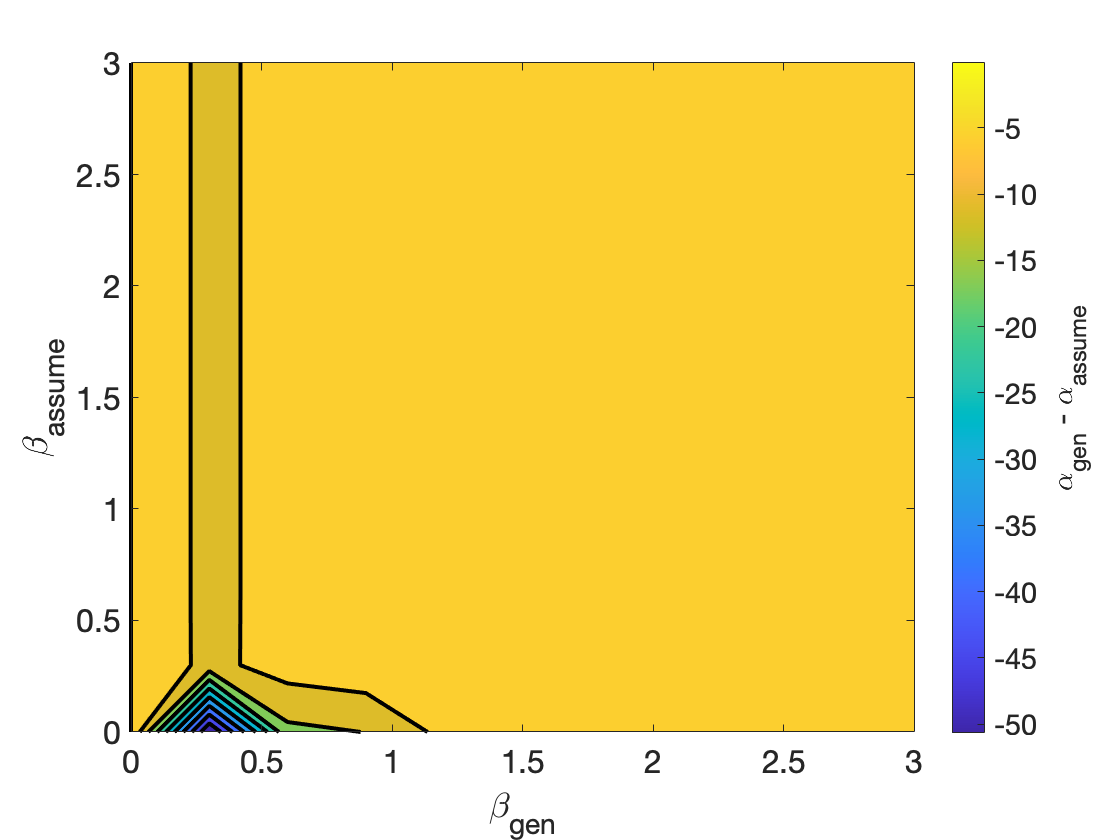

clear; clc;

% beta 
beta_gen = 0:0.3:3;
beta_assume =  0:0.3:3;
nSims = 30; 
betaSim = nan([length(beta_gen), length(beta_assume), nSims]);
for i = 1:length(beta_gen)
    for j = 1:length(beta_assume)
        for k = 1:nSims
            betaSim(i,j,k) = UpDownSim(1,1,[0.4,0.4], 0, beta_gen(i), 0.01, 0.5, beta_assume(j), 0.01, 0.5); 
        end
    end
end
% visualize 
figure;
[x,y] = meshgrid(beta_gen, beta_assume); 
avgSims = mean(betaSim,3); 
contourf(x,y,avgSims, linspace(min(min(avgSims)), max(max(avgSims)), 10), 'linewidth', 2); 
c = colorbar('ticks', round(linspace(min(min(avgSims)), max(max(avgSims)), 10),3));
c.Label.String = '\alpha_{gen} - \alpha_{assume}';
xlabel('\beta_{gen}'); ylabel('\beta_{assume}'); 
set(gca, 'FontSize', 16)